## Demonstrate estimating the significance levels for a set of EOFs

jwilkin@rutgers.edu

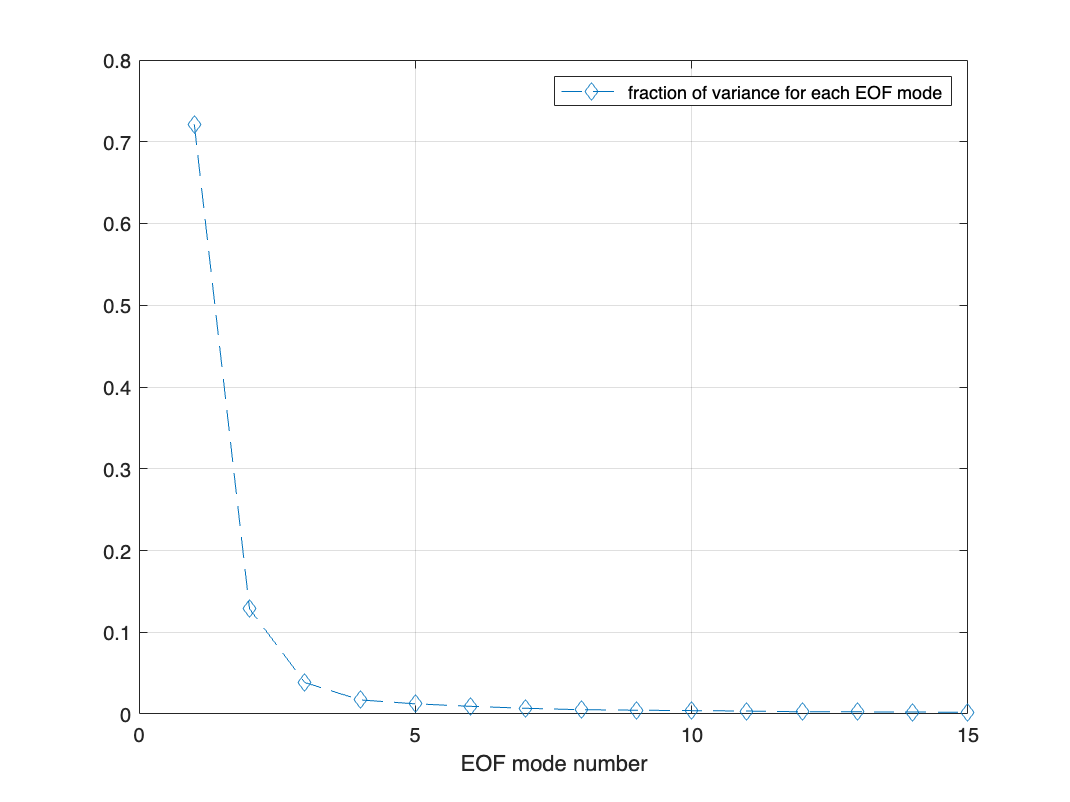

% The EOF analysis of CAC (Reynolds) SST data must have already
% been done by running live script script demo_1_cac_sst_eofs.mlx

% set up data matrix D by running demo_1_cac_sst_eofs with rmann = true

% Plot fractional variance of first K modes ("scree" plot)
K = 15;
figure
plot(diag(S*S')/trace(S*S'),'--d')
xlim([0 K])
legend('fraction of variance for each EOF mode')
xlabel('EOF mode number')
grid on

#### Monte Carlo estimate of 95% significance level for a random noise data set of the same size as D 

[M, N] = size(D);
nsamples = 100; % a bit small but otherwise takes too long in class
f95 = eofsig_montecarlo(M,N,nsamples);

Doing sample 10
Doing sample 20
Doing sample 30
Doing sample 40
Doing sample 50
Doing sample 60
Doing sample 70
Doing sample 80
Doing sample 90
Doing sample 100


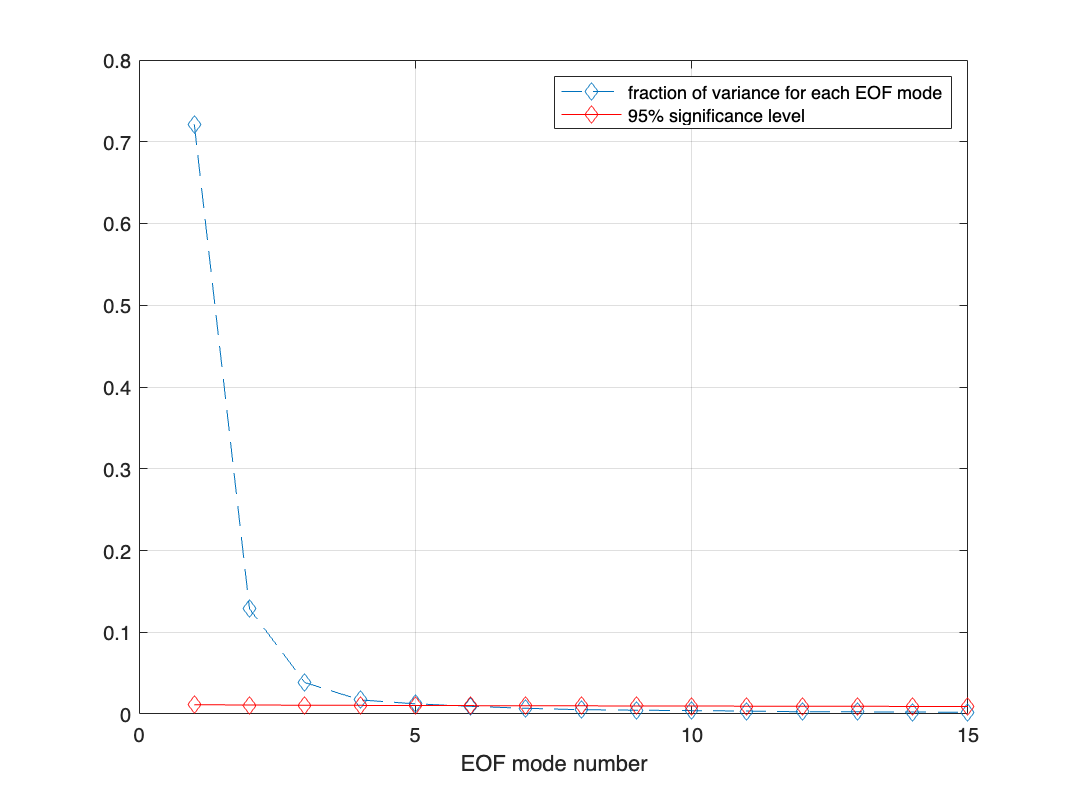


frac = diag(S*S')/trace(S*S');
plot(1:K,frac(1:K),'--d',1:K,f95(1:K),'r-d')
xlim([0 K])
grid on
legend('fraction of variance for each EOF mode','95% significance level')
xlabel('EOF mode number')


% For EOFs that have significant autocorrelation (say in time dimension)
% it is recommended that N be reduced to Nstar = N/autocorrelation_scale to
% reflect the number of independent observations in each row of the data
% matrix. See Joliffe (2002) 'Principal Component Analysis,' Springer
% Series in Statistics, chapter 6 and references therein.

% We can see that recomputing EOFs for a modestly decimated data set we get
% the exact same answer.

#### Re-compute the EOFs using only every n'th value in the time series

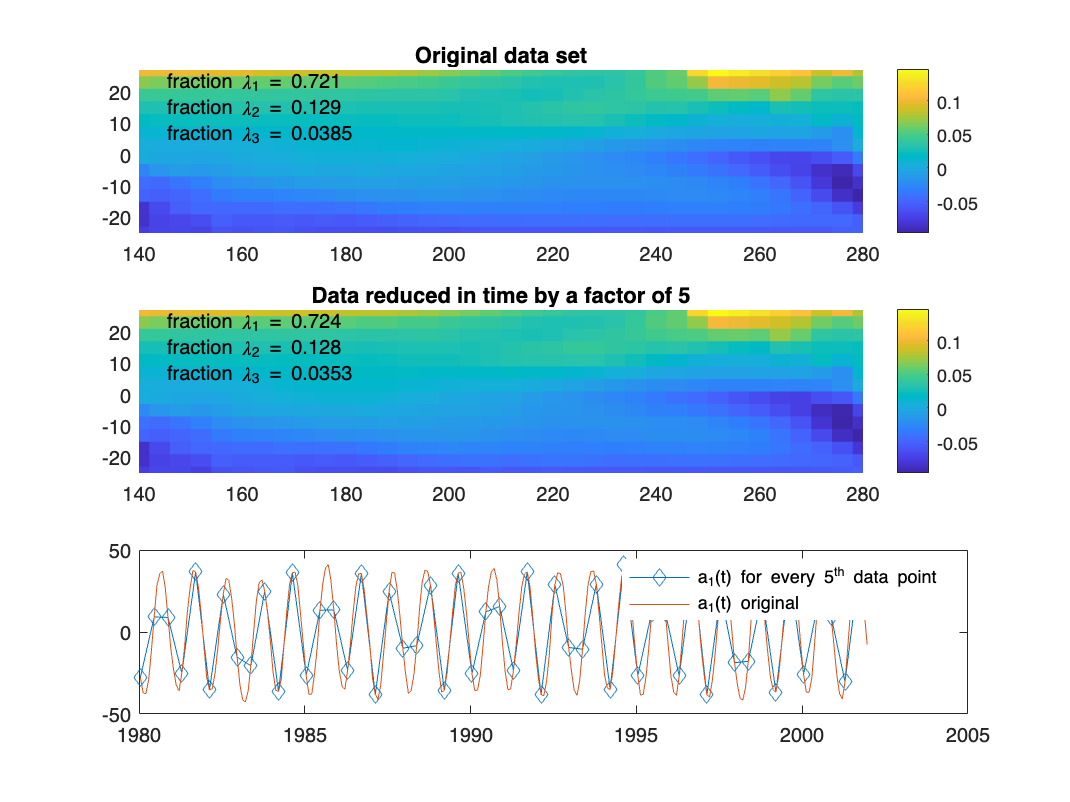

figure

[U,S,V] = svd(D,0);
A = S*V';
frac = diag(S*S')/trace(S*S');
lab{1} = ['fraction \lambda_1 = ' num2str(frac(1),3)];
lab{2} = ['fraction \lambda_2 = ' num2str(frac(2),3)];
lab{3} = ['fraction \lambda_3 = ' num2str(frac(3),3)];
subplot(311)
pcolorjw(lon,lat,reshape(U(:,1),[nlats nlons]))
cax = caxis;
colorbar
text(145,15,lab,'color','k')
title('Original data set')

n = 5; % decimate the time series by this factor to explore whether the 
       % results change (information is lost) or stay the same (probably
       % have data that is not independent) 
Dn = D(:,1:n:end);
yearn = year(1:n:end);
[Un,Sn,Vn] = svd(Dn,0);
An = Sn*Vn';
fracn = diag(Sn*Sn')/trace(Sn*Sn');
lab{1} = ['fraction \lambda_1 = ' num2str(fracn(1),3)];
lab{2} = ['fraction \lambda_2 = ' num2str(fracn(2),3)];
lab{3} = ['fraction \lambda_3 = ' num2str(fracn(3),3)];
subplot(312)
pcolorjw(lon,lat,reshape(Un(:,1),[nlats nlons]))
caxis(cax)
colorbar
text(145,15,lab,'color','k')
title(['Data reduced in time by a factor of ' int2str(n)])

subplot(313)
pcolorjw(lon,lat,reshape(U(:,1)-Un(:,1),[nlats nlons]))
colorbar
plot(year(1:n:end),An(1,:),'d-',year,A(1,:),'-')
legend(['a_1(t) for every ' int2str(n) '^{th} data point'],'a_1(t) original');
legend boxoff


% The EOFs look the same because monthly data resolve the variability well

% Recompute the Monte Carlo significance estimate

[M, N] = size(Dn);
nsamples = 100; % small but otherwise this step takes too long in class
f95_n = eofsig_montecarlo(M,N,nsamples);

Doing sample 10
Doing sample 20
Doing sample 30
Doing sample 40
Doing sample 50
Doing sample 60
Doing sample 70
Doing sample 80
Doing sample 90
Doing sample 100


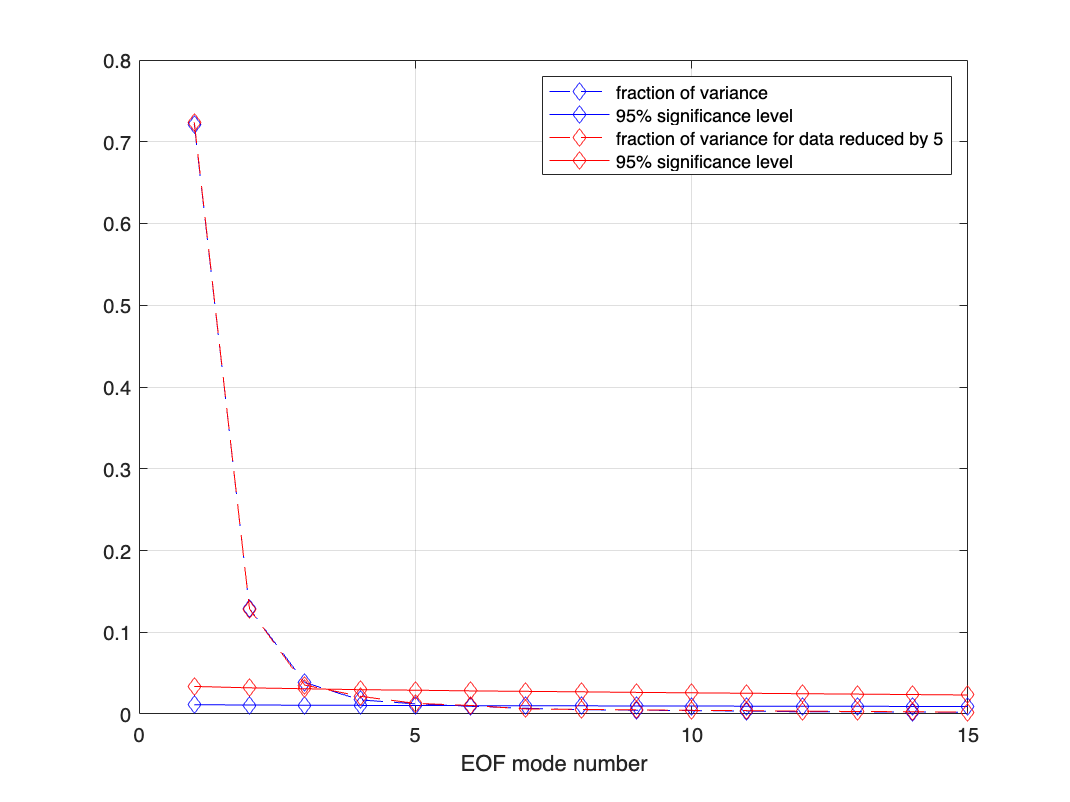


figure
plot(1:K,frac(1:K),'--bd',1:K,f95(1:K),'b-d',...
  1:K,fracn(1:K),'--rd',1:K,f95_n(1:K),'r-d')
grid on
legend('fraction of variance','95% significance level',...
  ['fraction of variance for data reduced by ' int2str(n)],...
  '95% significance level')
xlabel('EOF mode number')

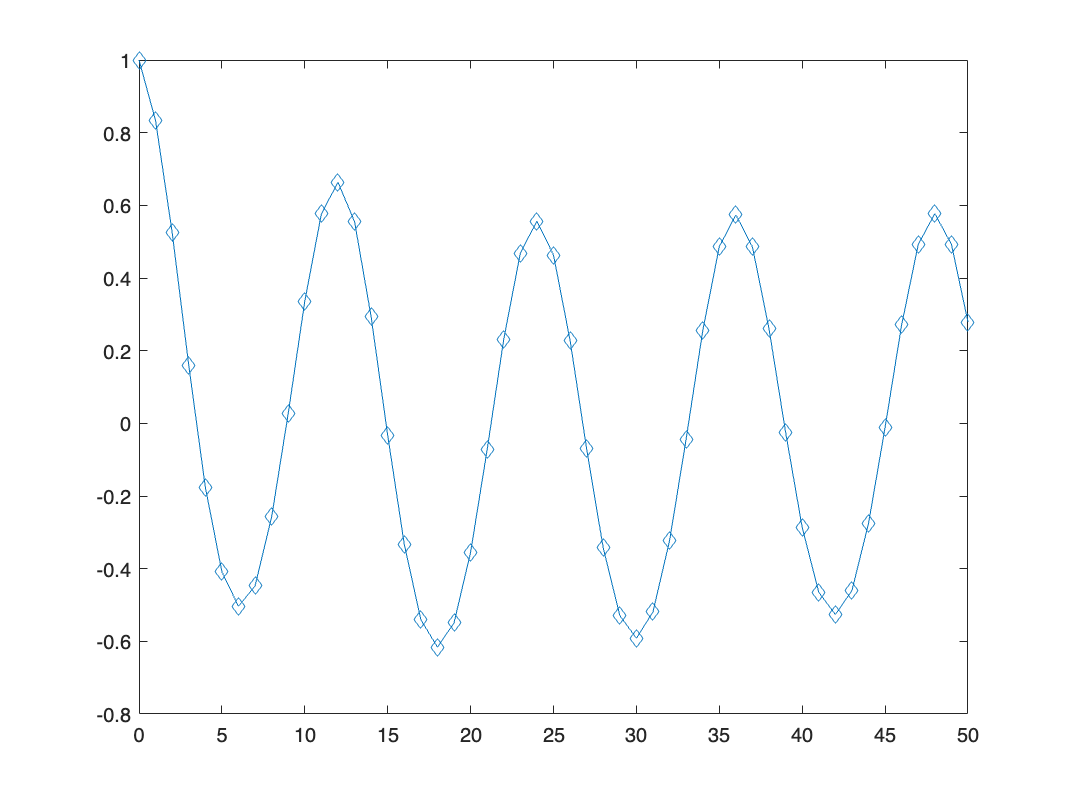

% How do we objectively estimate the effective degrees of freedom of the
% time sampling of the data? The answer lies in calculating the
% autocorrelation time scale, and assuming that the number of independent
% time samples is the duration of the time series divided by the
% autocorrelation time scale.

% One way of estimating the autocorrelation time scale is to form an
% ensemble autocorrelation function by averaging the auto-correlation
% sequences estimated for each time series, then integrating this out to
% the first zero crossing i.e. the time lag at which, on average, a time
% series becomes uncorrelated with itself.

% Use my function degreesfreedom.m to estimate the effective d.o.f.
[dof,Tscale,xc,lags] = degreesfreedom(D);
figure
plot(lags,xc,'d-')
xlim([0 50])

disp(' ')

disp(['Estimated D.O.F. are ' int2str(dof)])

Estimated D.O.F. are 104


disp(' ')

disp(['Autocorrelation Tscale is ' num2str(Tscale) ' sampling ',...
  'intervals of the data'])

Autocorrelation Tscale is 2.5184 sampling intervals of the data



% Recompute significance limits using DOF = N/Tscale instead of N.
nsamples = 1000; % small, but otherwise this step takes too long in class
[f95_dof,Fs_dof] = eofsig_montecarlo(M,dof,nsamples);

Doing sample 100
Doing sample 200
Doing sample 300
Doing sample 400
Doing sample 500
Doing sample 600
Doing sample 700
Doing sample 800
Doing sample 900
Doing sample 1000


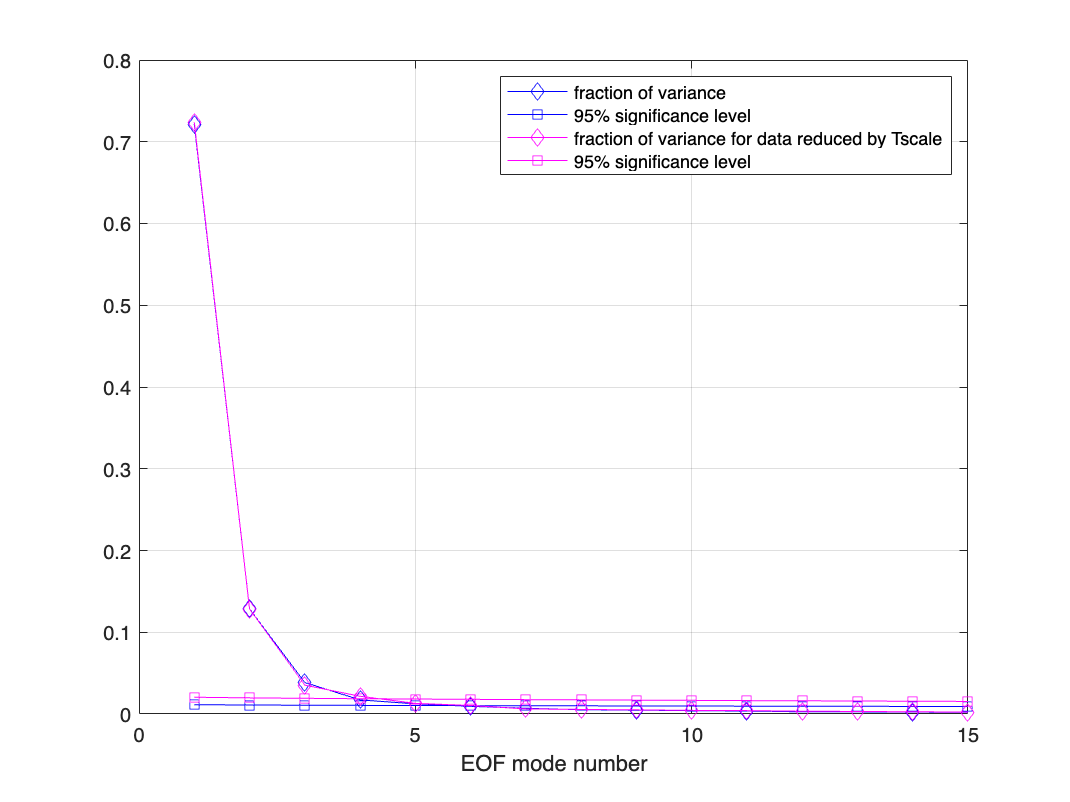


figure
plot(1:K,frac(1:K),'-bd',1:K,f95(1:K),'b-s',...
  1:K,fracn(1:K),'-md',1:K,f95_dof(1:K),'m-s');
grid on
legend('fraction of variance','95% significance level',...
  'fraction of variance for data reduced by Tscale','95% significance level')
xlabel('EOF mode number')

#### Histogram of set of first mode eigenvalues

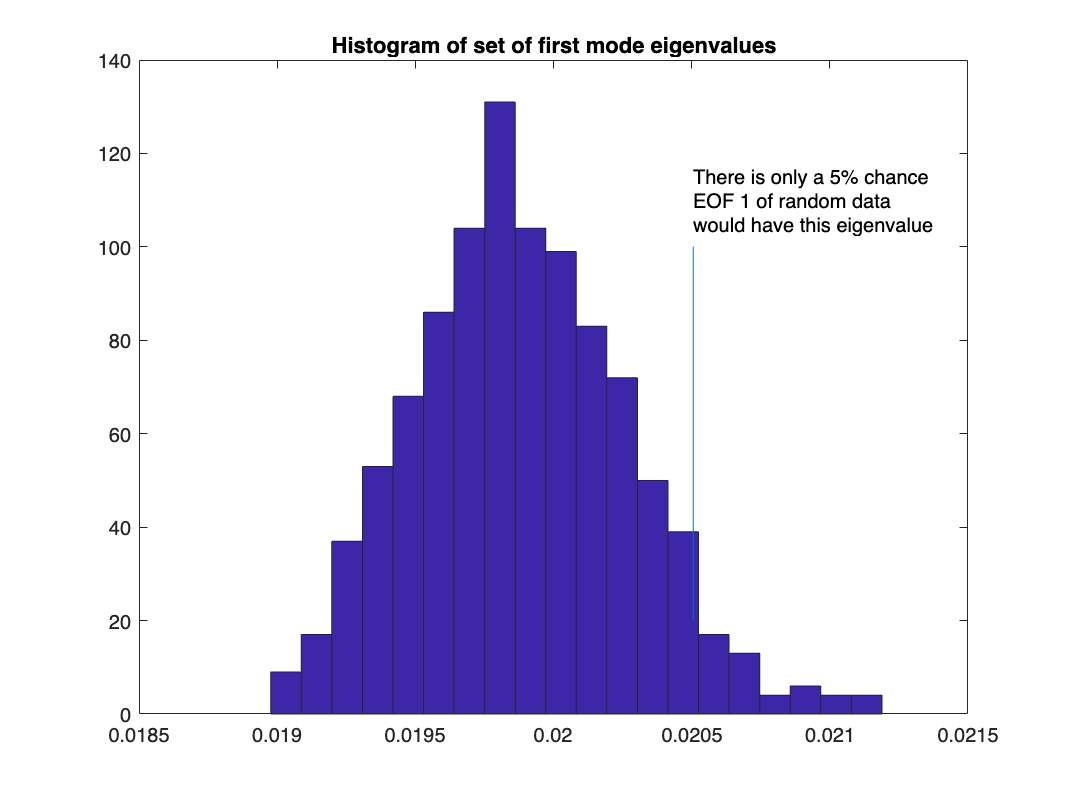

figure
hist(Fs_dof(1,:),20)
title('Histogram of set of first mode eigenvalues')
hold on
plot([f95_dof(1) f95_dof(1)],[20 100])
text(f95_dof(1),110,{'There is only a 5% chance','EOF 1 of random data',...
  'would have this eigenvalue'})
hold off

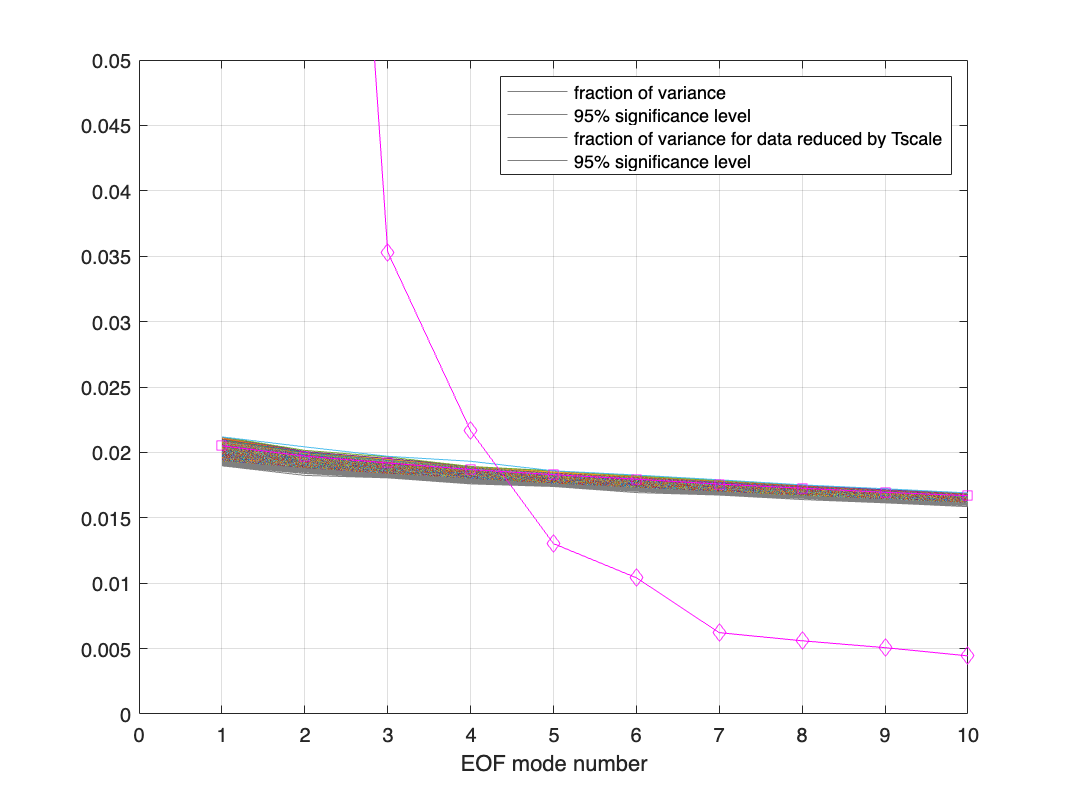

figure
han = plot(1:K,Fs_dof(1:K,:),'-',...
  1:K,fracn(1:K),'-md',1:K,f95_dof(1:K),'m-s');
set(han(1:100),'color',0.5*[1 1 1])
grid on
axis([0 10 0 0.05])
legend('fraction of variance','95% significance level',...
  'fraction of variance for data reduced by Tscale','95% significance level')
xlabel('EOF mode number')

#### North's rule of thumb

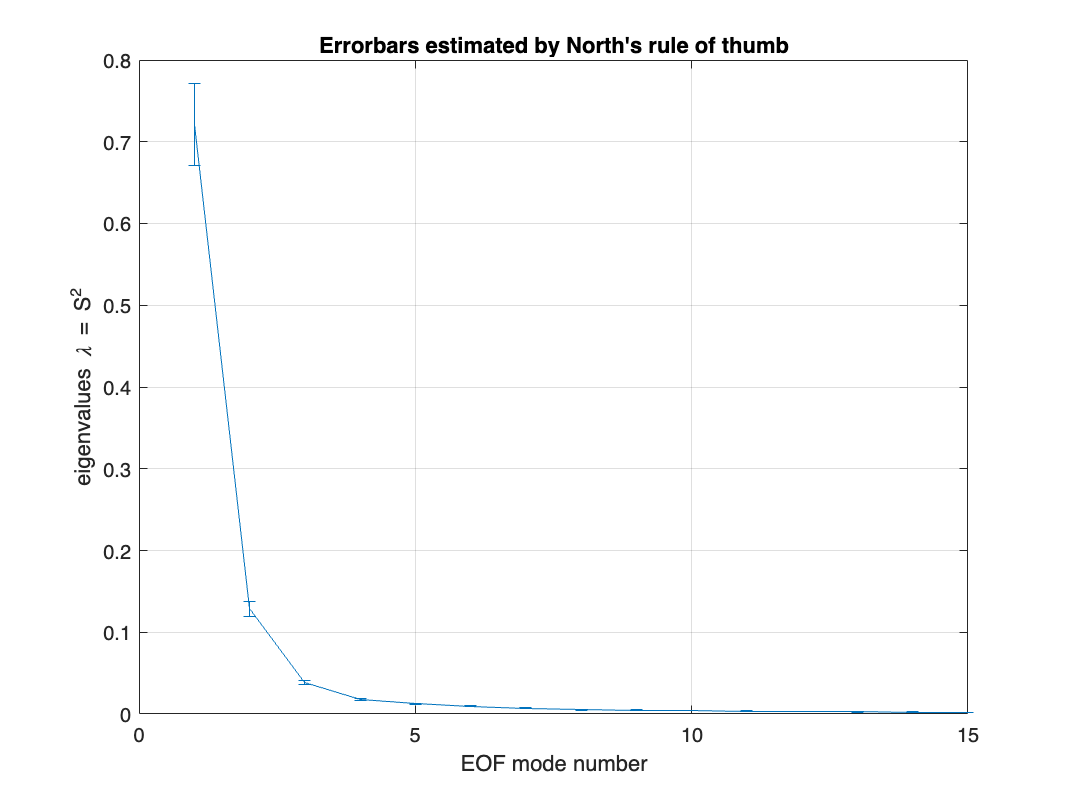

figure
Lambda = diag(S*S');
Lambda = Lambda/sum(Lambda);

% North's estimate dL scales with lambda so it's ok to use normalized
% values
dL = 0.5*Lambda*sqrt(2/dof); % half for symmetric upper and lower bounds
errorbar(1:K,Lambda(1:K),dL(1:K),dL(1:K))
grid on
ylabel('eigenvalues \lambda = S^2')
xlabel('EOF mode number')
title('Errorbars estimated by North''s rule of thumb')